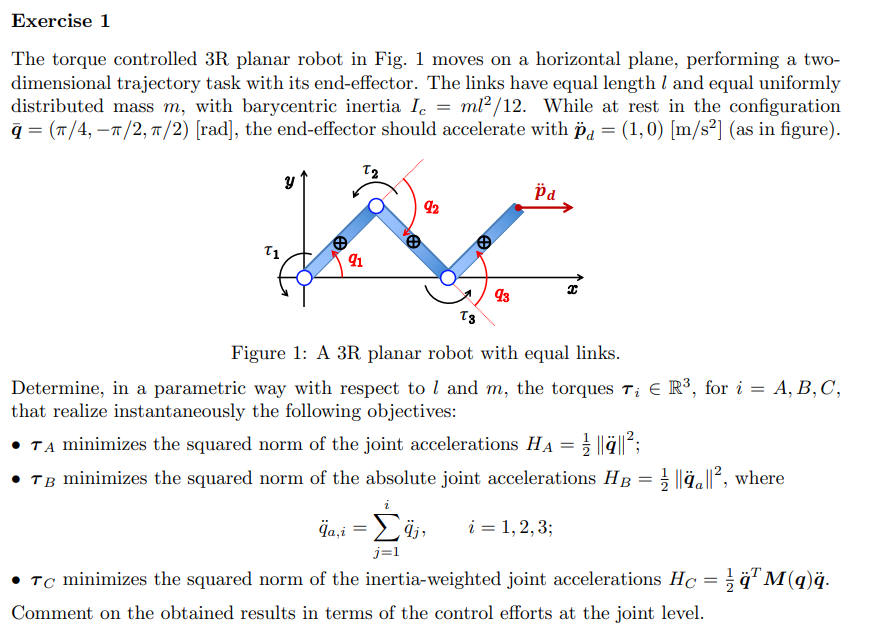

clc
clear all
close all

% addpath("Functions/Robotics1") % Linux
% addpath("Functions/Robotics2") % Linux
addpath("Functions\Robotics1") % Windows
addpath("Functions\Robotics2") % Windows

syms q_1 q_2 q_3 q_dot_1 q_dot_2 q_dot_3 q_dot_dot_1 q_dot_dot_2 q_dot_dot_3 real
syms l m_1 g0 real

q = [q_1 q_2 q_3]';
q_dot=[q_dot_1 q_dot_2 q_dot_3]';
q_dot_dot=[q_dot_dot_1 q_dot_dot_2 q_dot_dot_3]';

pc1 = [l/2*cos(q_1) l/2*sin(q_1) 0]';
pc2 = [l*cos(q_1) + l/2*cos(q_1+q_2) l*sin(q_1) + l/2*sin(q_1+q_2) 0]';
pc3 = [l*cos(q_1) + l*cos(q_1+q_2) + l/2*cos(q_1+q_2+q_3) l*sin(q_1) + l*sin(q_1+q_2) + l/2*sin(q_1+q_2+q_3) 0]';

f = [l*cos(q_1) + l*cos(q_1+q_2) + l*cos(q_1+q_2+q_3) l*sin(q_1) + l*sin(q_1+q_2) + l*sin(q_1+q_2+q_3)]';
J = jacobian(f, q);

vc1 = jacobian(pc1, q)*q_dot;
vc2 = jacobian(pc2, q)*q_dot;
vc3 = jacobian(pc3, q)*q_dot;

omega1 = [0 0 q_dot_1]';
omega2 = [0 0 q_dot_1 + q_dot_2]';
omega3 = [0 0 q_dot_1 + q_dot_2 + q_dot_3]';

i_r_ci = [pc1 pc2 pc3];
v_ci = [vc1 vc2 vc3];
omegai = [omega1 omega2 omega3];

m = [m_1 m_1 m_1]';

g = [0 0 -g0]';

I = inertia_matrix(3);
I(:,:,1)=(m_1*(l^2)/12)*eye(3);
I(:,:,2)=(m_1*(l^2)/12)*eye(3);
I(:,:,3)=(m_1*(l^2)/12)*eye(3);

%dynamics
[M, c, g_fun, u] = lagrange_dynamic(q, q_dot, q_dot_dot, m, g, I, i_r_ci, 0, 0, 0, 0, 0, v_ci, omegai);
M_q = subs(M, q, [pi/4 -pi/2 pi/2]');

% use the configurationa and rest velociteis
u_q = subs(u, q, [pi/4 -pi/2 pi/2]');
u_q = subs(u_q, q_dot, [0 0 0]');

%task
p_dd = [1 0]';

% tau_A such that min 1/2 ||q||^2
q_dd_a = simplify(pinv(J)*p_dd);
q_dd_A = vpa(subs(q_dd_a, q, [pi/4 -pi/2 pi/2]'), 5);
u_A = vpa(M_q*q_dd_A, 5);

% tau_B such that min 1/2 ||q_a||^2, q_a = absolute value of q
T = zeros(3);
T(tril(true(3))) = 1;
% i pesi si mettono tra un quadrato di q -> q*W*q quindi T deve essere
% simmetrico poi si usa l'inverso di questo peso
W = inv(T'*T);
J_pinv_W = simplify(W*J'*inv(J*W*J'));
q_dd_b = simplify(J_pinv_W*p_dd);
q_dd_B = vpa(subs(q_dd_b, q, [pi/4 -pi/2 pi/2]'), 5);
u_B = vpa(M_q*q_dd_B, 5);

% tau_B such that min 1/2 q'*M*q -> come primo modo ma con peso M
M_q_inv = inv(M_q);
J_pinv_M = simplify(M_q_inv*J'*inv(J*M_q_inv*J'));
q_dd_c = simplify(J_pinv_M*p_dd);
q_dd_C = vpa(subs(q_dd_c, q, [pi/4 -pi/2 pi/2]'), 5);
u_C = vpa(M_q*q_dd_C, 5);

% print q
q_dd_A

$$q\_dd\_A = \left(\begin{array}{c} -\frac{0.2357}{l}\\ \frac{0.94281}{l}\\ -\frac{1.1785}{l} \end{array}\right)$$

q_dd_B

$$q\_dd\_B = \left(\begin{array}{c} -\frac{0.35355}{l}\\ \frac{1.0607}{l}\\ -\frac{1.0607}{l} \end{array}\right)$$

q_dd_C

$$q\_dd\_C = \left(\begin{array}{c} \frac{0.070711}{l}\\ \frac{0.6364}{l}\\ -\frac{1.4849}{l} \end{array}\right)$$

% print tau
u_A

$$u\_A = \left(\begin{array}{c} -0.11785\,l\,m_{1}\\ 0.66782\,l\,m_{1}\\ -0.27499\,l\,m_{1} \end{array}\right)$$

u_B

$$u\_B = \left(\begin{array}{c} -0.35355\,l\,m_{1}\\ 0.64818\,l\,m_{1}\\ -0.29463\,l\,m_{1} \end{array}\right)$$

u_C

$$u\_C = \left(\begin{array}{c} 0.49497\,l\,m_{1}\\ 0.71889\,l\,m_{1}\\ -0.22392\,l\,m_{1} \end{array}\right)$$